# **时序空间端点匹配算法**

封装函数备用行

% function[Ruler_Observe_match] = MainRulerMatch(CamRuler,CamNum,RulerNum)

## Step1. 数据读取与设置

clc;clear;close all;
CamRuler{1}=load('C:\Users\Kylin\Desktop\On-site measurement\OnsiteALLtest_1\picset\Cam1_Ruler\pointStructure.mat');
CamRuler{2}=load('C:\Users\Kylin\Desktop\On-site measurement\OnsiteALLtest_1\picset\Cam2_Ruler\pointStructure.mat');
CamRuler{3}=load('C:\Users\Kylin\Desktop\On-site measurement\OnsiteALLtest_1\picset\Cam3_Ruler\pointStructure.mat');
CamRuler{4}=load('C:\Users\Kylin\Desktop\On-site measurement\OnsiteALLtest_1\picset\Cam4_Ruler\pointStructure.mat');
CamNum=4;
RulerNum=4;

PointDistribution=0;%状态判断变量

## Step2. 判断长度端点分布构型

### 1.判断左右或上下点分布构型

Step2整体为双层循环结构：首先处理同一个空间长度在不同相机像面中的点分类，再以空间长度为顺序进行遍历处理

for RulerOrder=1:RulerNum%

    for CamOrder=1:CamNum

        Rulerpoint=CamRuler{1, CamOrder}.pointStructure(RulerOrder).point;
        Rulerpoint_DeltX=abs(Rulerpoint(1,2)-Rulerpoint(2,2));%两端点坐标xy相减取绝对值判断是上下构型还是左右构型
        Rulerpoint_DeltY=abs(Rulerpoint(1,3)-Rulerpoint(2,3));

        if Rulerpoint_DeltX>Rulerpoint_DeltY %左右构型
            PointDistribution=1;%左右分布
                if Rulerpoint(1,2)<Rulerpoint(2,2)
                        left_point(CamOrder,:)=Rulerpoint(1,2:4);
                        right_point(CamOrder,:)=Rulerpoint(2,2:4);
                else
                        right_point(CamOrder,:)=Rulerpoint(1,2:4);
                        left_point(CamOrder,:)=Rulerpoint(2,2:4);
                end

        else%上下构型
            PointDistribution=2;%上下分布
                if Rulerpoint(1,3)<Rulerpoint(2,3)
                        up_point(CamOrder,:)=Rulerpoint(2,2:4);
                        down_point(CamOrder,:)=Rulerpoint(1,2:4);
                else
                        down_point(CamOrder,:)=Rulerpoint(2,2:4);
                        up_point(CamOrder,:)=Rulerpoint(1,2:4);
                end
            
            
        end



    end

### 2.根据点分布构型进行数据写入


        if PointDistribution==1%左右分布
                left_point(:,3)=2*RulerOrder-1;
                right_point(:,3)=2*RulerOrder;
                
        else%上下分布
                up_point(:,3)=2*RulerOrder-1;
                down_point(:,3)=2*RulerOrder;
                
        end

### 3.不同相机相同点的数据整理工作


for CamOrder=1:CamNum %不同相机相同点的整理工作

    if PointDistribution==1%左右分布

Ruler_Observe_match{CamOrder}(2*RulerOrder-1,:)=left_point(CamOrder,:);
Ruler_Observe_match{CamOrder}(2*RulerOrder,:)=right_point(CamOrder,:);

    else

Ruler_Observe_match{CamOrder}(2*RulerOrder-1,:)=up_point(CamOrder,:);
Ruler_Observe_match{CamOrder}(2*RulerOrder,:)=down_point(CamOrder,:);

    end

end

end


## Step3. 绘图检查匹配结果

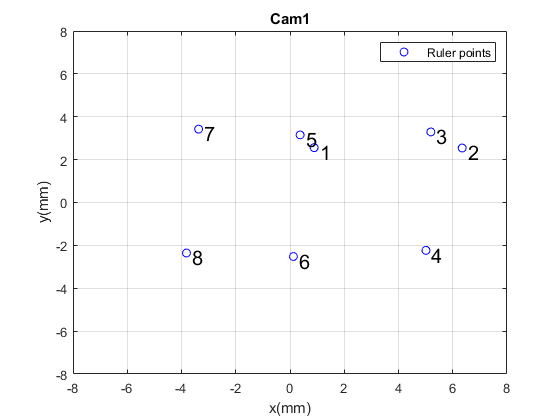

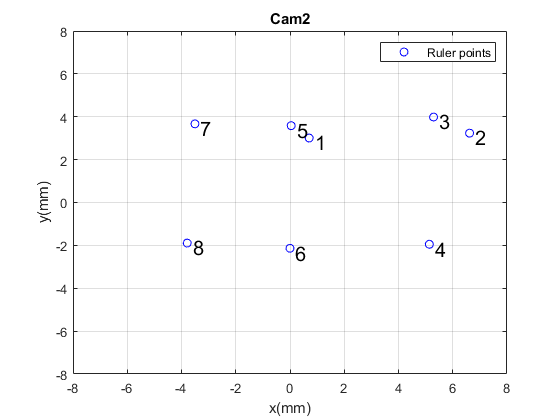

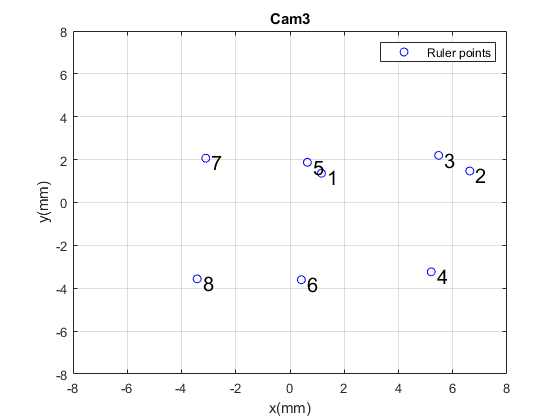

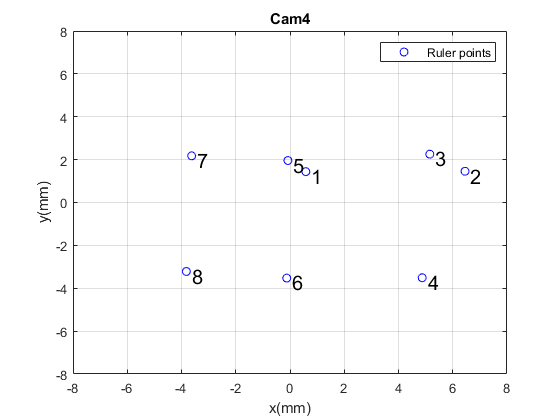


for i=1:CamNum
    figure(i)
plot(Ruler_Observe_match{i}(:,1),Ruler_Observe_match{i}(:,2),'bo');
text(Ruler_Observe_match{i}(:,1)+0.2,Ruler_Observe_match{i}(:,2)-0.2,[num2str(Ruler_Observe_match{i}(:,3))],'FontSize',15)
xlim([-8 8]);
ylim([-8 8]);
grid on
legend("Ruler points")
title(['Cam',num2str(i)])
xlabel("x(mm)")
ylabel("y(mm)")
end